# Classify Query Data

This example shows how to classify query data by:

- Growing a *K*d-tree

- Conducting a *k* nearest neighbor search using the grown tree.

- Assigning each query point the class with the highest representation among their respective nearest neighbors.

Classify a new point based on the last two columns of the Fisher iris data. Using only the last two columns makes it easier to plot.

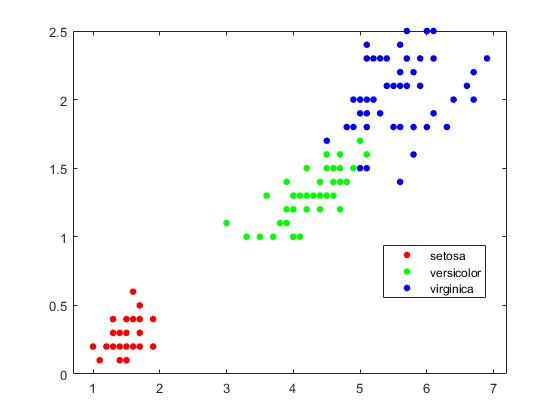

load fisheriris
x = meas(:,3:4);
gscatter(x(:,1),x(:,2),species)
legend('Location','best')

Plot the new point.

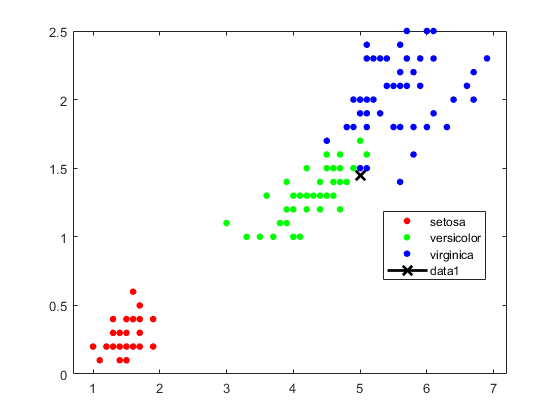

newpoint = [5 1.45];
line(newpoint(1),newpoint(2),'marker','x','color','k',...
   'markersize',10,'linewidth',2)

Mdl = KDTreeSearcher(x)

Mdl =   KDTreeSearcher - 属性:

       BucketSize: 50
         Distance: 'euclidean'
    DistParameter: []
                X: [150×2 double]


`Mdl` is a `KDTreeSearcher` model. By default, the distance metric it uses to search for neighbors is Euclidean distance.

Find the 10 sample points closest to the new point.Prepare a *K*d-tree neighbor searcher model.

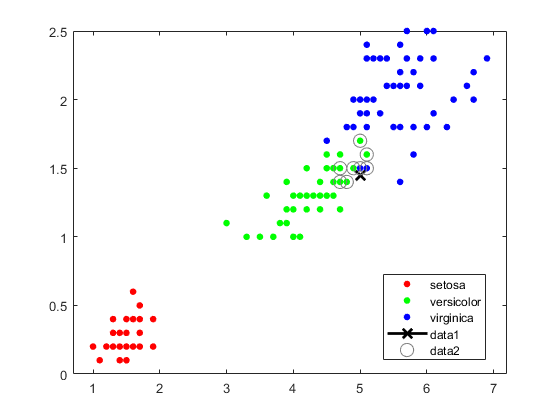


[n,d] = knnsearch(Mdl,newpoint,'k',10);
line(x(n,1),x(n,2),'color',[.5 .5 .5],'marker','o',...
    'linestyle','none','markersize',10)

It appears that `knnsearch` has found only the nearest eight neighbors. In fact, this particular dataset contains duplicate values.

x(n,:)

ans =                          5                       1.5
                       4.9                       1.5
                       4.9                       1.5
                       5.1                       1.5
                       5.1                       1.6
                       4.8                       1.4
                         5                       1.7
                       4.7                       1.4
                       4.7                       1.4
                       4.7                       1.5


Make the axes equal so the calculated distances correspond to the apparent distances on the plot axis equal and zoom in to see the neighbors better.

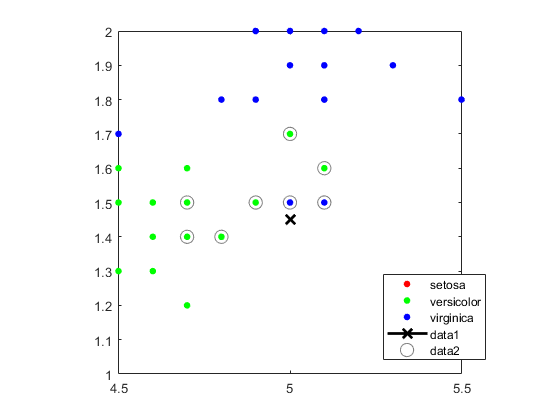

xlim([4.5 5.5]);
ylim([1 2]);
axis square

Find the species of the 10 neighbors.

tabulate(species(n))

       Value    Count   Percent
   virginica        2     20.00%
  versicolor        8     80.00%


Using a rule based on the majority vote of the 10 nearest neighbors, you can classify this new point as a versicolor.

Visually identify the neighbors by drawing a circle around the group of them. Define the center and diameter of a circle, based on the location of the new point.

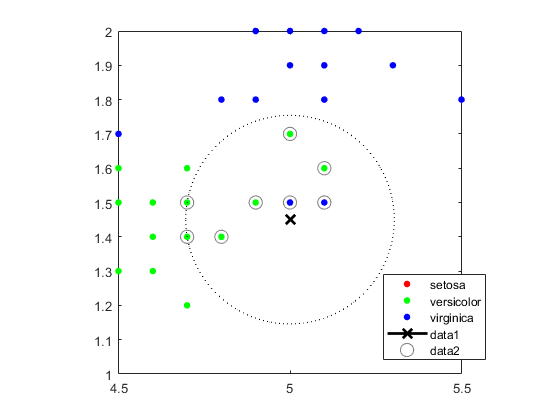

ctr = newpoint - d(end);
diameter = 2*d(end);
% Draw a circle around the 10 nearest neighbors.
h = rectangle('position',[ctr,diameter,diameter],...
   'curvature',[1 1]);
h.LineStyle = ':';

Using the same dataset, find the 10 nearest neighbors to three new points.

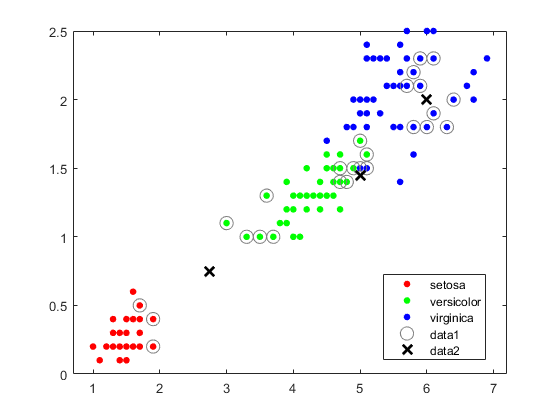

figure 
newpoint2 = [5 1.45;6 2;2.75 .75];
gscatter(x(:,1),x(:,2),species)
legend('location','best')
[n2,d2] = knnsearch(Mdl,newpoint2,'k',10);
line(x(n2,1),x(n2,2),'color',[.5 .5 .5],'marker','o',...
   'linestyle','none','markersize',10)
line(newpoint2(:,1),newpoint2(:,2),'marker','x','color','k',...
   'markersize',10,'linewidth',2,'linestyle','none')

Find the species of the 10 nearest neighbors for each new point.

tabulate(species(n2(1,:)))

       Value    Count   Percent
   virginica        2     20.00%
  versicolor        8     80.00%


tabulate(species(n2(2,:)))

      Value    Count   Percent
  virginica       10    100.00%


tabulate(species(n2(3,:)))

       Value    Count   Percent
  versicolor        7     70.00%
      setosa        3     30.00%


For more examples using `knnsearch` methods and function, see the individual reference pages.

*Copyright 2012 The MathWorks, Inc.*